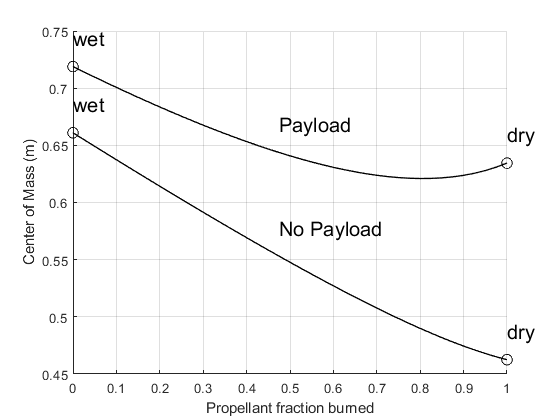

%%%%%%%%% Setup %%%%%%%%%%
r_lox_wet = 1.04;
r_lox_dry = 0.74;

r_fuel_wet = 0.52;
r_fuel_dry = 0.30;

r_eng = 0.2;
r_body = 0.83;
r_load = 1.46;

m_prop_max = 20;
m_load = 5;
m_eng = 14;
m_body = 10;
%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%% Mass calc %%%%%%%%
m_dry = [m_eng + m_body; m_load + m_eng + m_body];
m_wet = 2*m_prop_max + m_dry;
m_burn = 0:0.5:(m_prop_max);

m = m_wet-2*m_burn;
m_prop = m_prop_max-m_burn;
%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%% CM calc %%%%%%%%
r_dry = [(m_body*r_body + m_eng*r_eng)./m_dry(1);
         (m_load*r_load + m_body*r_body + m_eng*r_eng)./m_dry(2)];
r_lox = m_prop/m_prop_max*(r_lox_wet - r_lox_dry) + r_lox_dry;
r_fuel = m_prop/m_prop_max*(r_fuel_wet - r_fuel_dry) + r_fuel_dry;
r_wet = [(m_prop_max*r_lox_wet + m_dry.*r_dry + m_prop_max*r_fuel_wet)./m_wet];

r = [((m_prop).*(r_lox + r_fuel) + m_dry.*r_dry)./m];
cm_lookup = [r(1,1), r(1,end)];
%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%% CM Plot %%%%%%%%%%%%%
lables = ["wet","dry","wet","dry","No Payload","Payload"];
coord_x = [m_burn(1)/m_prop_max, m_burn(end)/m_prop_max, m_burn(1)/m_prop_max, m_burn(end)/m_prop_max, m_burn(floor(end/2))/m_prop_max, m_burn(floor(end/2))/m_prop_max];
coord_y = [r(1,1)+0.025, r(1,end)+0.025, r(2,1)+0.025, r(2,end)+0.025, r(1,floor(end/2))+0.025, r(2,floor(end/2))+0.025];
blackPlotNoFit(m_burn/m_prop_max,r',lables,15,coord_x,coord_y,'Propellant fraction burned','Center of Mass (m)',8)

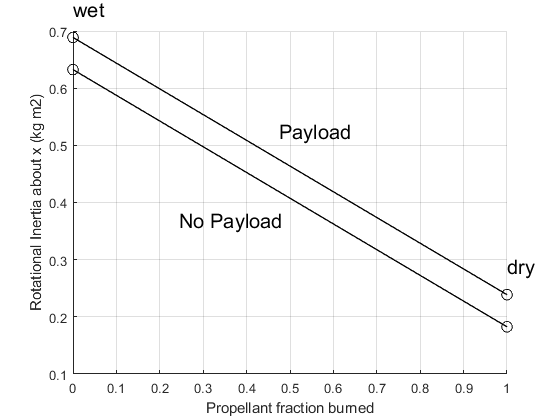

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%% Rot Inertia %%%%%%%%%%%
% lengths
l_load = 0.1;
l_body = 1.64;
l_eng = 0.3;
l_lox = (r_lox-r_lox_dry)*2;
l_fuel = (r_fuel-r_fuel_dry)*2;

% x axis
I_x_load = 0.5*m_load*0.15^2;
I_x_body = 0.5*m_body*0.15^2;
I_x_eng = 0.5*m_eng*0.1^2;
I_x_fuel = 0.5*m_prop.*0.15.^2;
I_x_lox = 0.5*m_prop.*0.15.^2;

I_x_dry = [I_x_body + I_x_eng;
           I_x_load + I_x_body + I_x_eng];
I_x = I_x_dry + I_x_lox + I_x_fuel;
I_x_lookup = [I_x(1,1), I_x(1,end)];

lables = ["wet","dry","No Payload","Payload"];
coord_x = [m_burn(1)/m_prop_max, m_burn(end)/m_prop_max, m_burn(floor(end/2))/m_prop_max-0.23, m_burn(floor(end/2))/m_prop_max];
coord_y = [I_x(2,1)+0.05, I_x(2,end)+0.05, I_x(1,floor(end/2))-0.05, I_x(2,floor(end/2))+0.05];
blackPlotNoFit(m_burn/m_prop_max,I_x',lables,15,coord_x,coord_y,'Propellant fraction burned','Rotational Inertia about x (kg m2)',8)

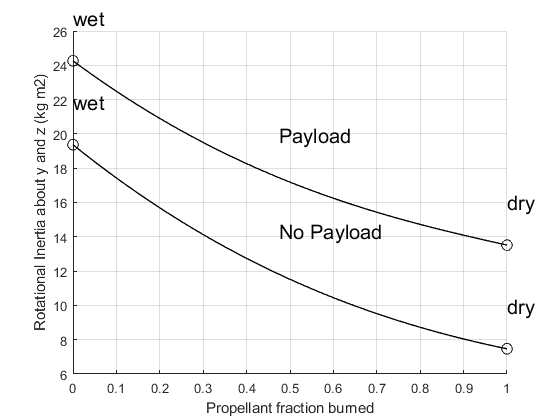


% yz axis
I_yz_load = m_load*(0.25*r_load^2 + 1/12*l_load^2);
I_yz_body = m_body*(0.25*r_body^2 + 1/12*l_body^2);
I_yz_eng = m_eng*(0.25*r_eng^2 + 1/12*l_eng^2);
I_yz_lox = m_prop.*(0.25*r_lox.^2 + 1/12*l_lox.^2);
I_yz_fuel = m_prop.*(0.25*r_fuel.^2 + 1/12*l_fuel.^2);

I_yz_dry = [I_yz_body + m_body*(r_body-r(1)).^2 + I_yz_eng + m_eng*(r_eng-r(1)).^2;
            I_yz_load + m_load*(r_load-r(2)).^2 + I_yz_body + m_body*(r_body-r(2)).^2 + I_yz_eng + m_eng*(r_eng-r(2)).^2];
I_yz = I_yz_dry + m_dry.*(r_dry-r).^2 + I_yz_fuel + m_prop.*(r_fuel-r).^2 + I_yz_lox + m_prop.*(r_lox-r).^2;
I_yz_lookup = I_yz(1,:);
lables = ["wet","wet","dry","dry","No Payload","Payload"];
coord_x = [m_burn(1)/m_prop_max, m_burn(1)/m_prop_max, m_burn(end)/m_prop_max, m_burn(end)/m_prop_max, m_burn(floor(end/2))/m_prop_max, m_burn(floor(end/2))/m_prop_max];
coord_y = [I_yz(1,1)+2.5, I_yz(2,1)+2.5, I_yz(1,end)+2.5, I_yz(2,end)+2.5, I_yz(1,floor(end/2))+2.5, I_yz(2,floor(end/2))+2.5];
blackPlotNoFit(m_burn/m_prop_max,I_yz',lables,15,coord_x,coord_y,'Propellant fraction burned','Rotational Inertia about y and z (kg m2)',8)